## Zadanie 1

x1 = -5:0.1:5;
x2 = 0:0.1:5;
x3 = -3:0.1:3;

y1 = x1.^2;
y2 = log(x2);
y3 = exp(x3);

**Podpunkt a)**

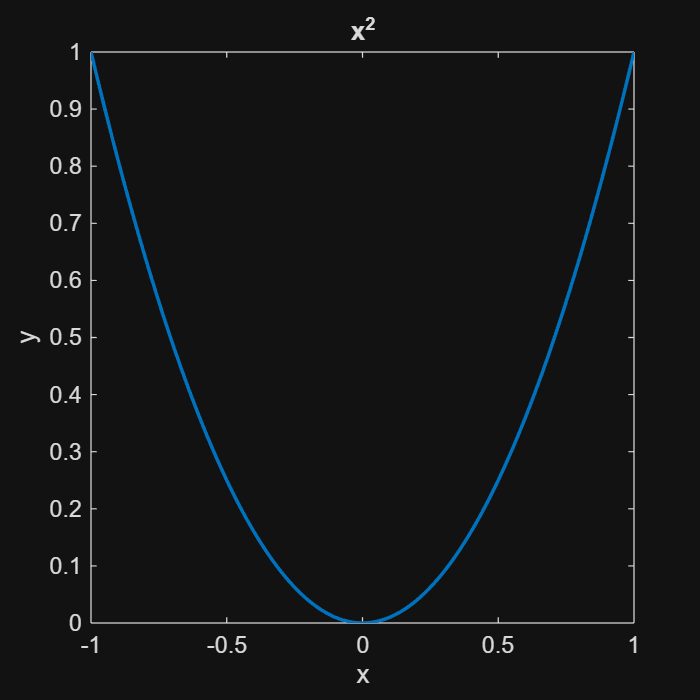

figure('Position', [100, 100, 400, 400]);
plot(x1, y1, 'LineWidth', 1.5, 'Color', '#0072BD');
title('x^2');
xlabel('x');
ylabel('y');

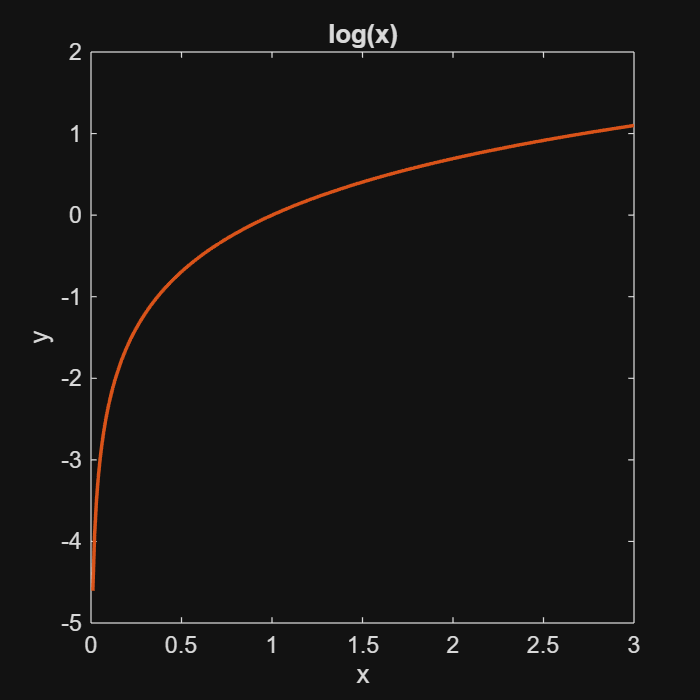

figure('Position', [100, 100, 400, 400]);
plot(x2, y2, 'LineWidth', 1.5, 'Color', '#D95319');
title('log(x)');
xlabel('x');
ylabel('y');

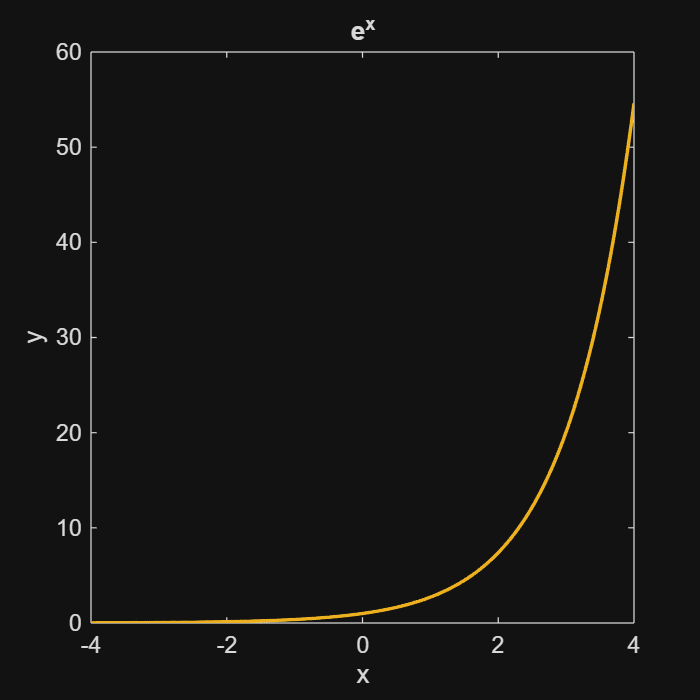

figure('Position', [100, 100, 400, 400]);
plot(x3, y3, 'LineWidth', 1.5, 'Color', '#EDB120');
title('e^x');
xlabel('x');
ylabel('y');

**Podpunkt b)**

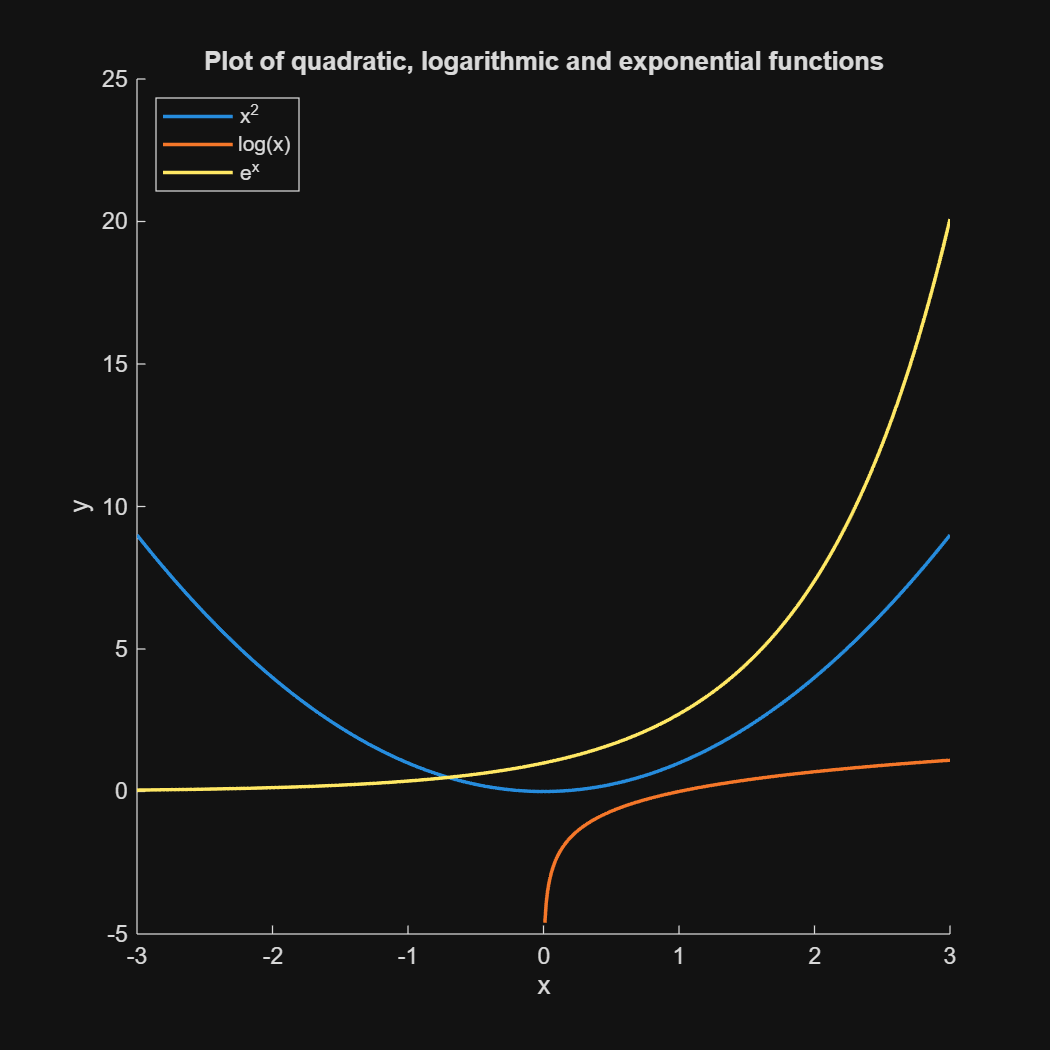

x1 = -3:0.01:3;
x2 = 0:0.01:3;
x3 = -3:0.01:3;

y1 = x1.^2;
y2 = log(x2);
y3 = exp(x3);

figure('Position', [100, 100, 600, 600]);
hold on;
plot(x1, y1, 'LineWidth', 1.5);
plot(x2, y2, 'LineWidth', 1.5);
plot(x3, y3, 'LineWidth', 1.5);
hold off;

title('Plot of quadratic, logarithmic and exponential functions');
xlabel('x');
ylabel('y');
legend('x^2', 'log(x)', 'e^x', 'Location', 'northwest');

**Podpunkt c)**

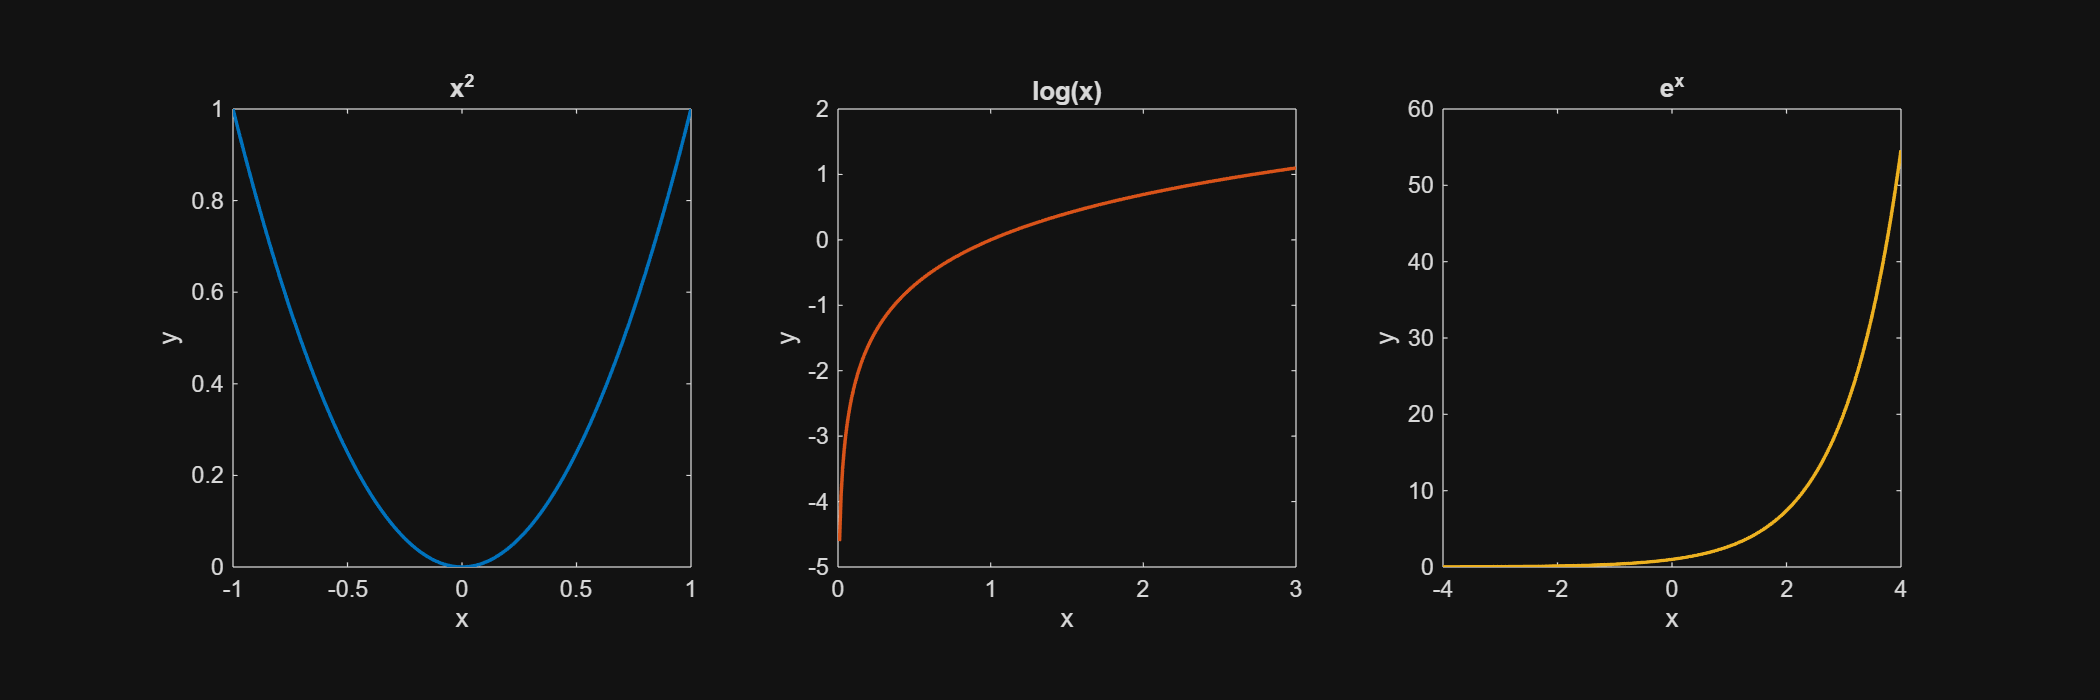

x1 = -1:0.01:1;
x2 = 0:0.01:3;
x3 = -4:0.01:4;

y1 = x1.^2;
y2 = log(x2);
y3 = exp(x3);

figure('Position', [100, 100, 1200, 400]);
tiledlayout(1, 3);

nexttile;
plot(x1, y1, 'LineWidth', 1.5, 'Color', '#0072BD');
title('x^2');
xlabel('x');
ylabel('y');
axis square;

nexttile;
plot(x2, y2, 'LineWidth', 1.5, 'Color', '#D95319');
title('log(x)');
xlabel('x');
ylabel('y');
axis square;

nexttile;
plot(x3, y3, 'LineWidth', 1.5, 'Color', '#EDB120');
title('e^x');
xlabel('x');
ylabel('y');
axis square;

## Zadanie 2

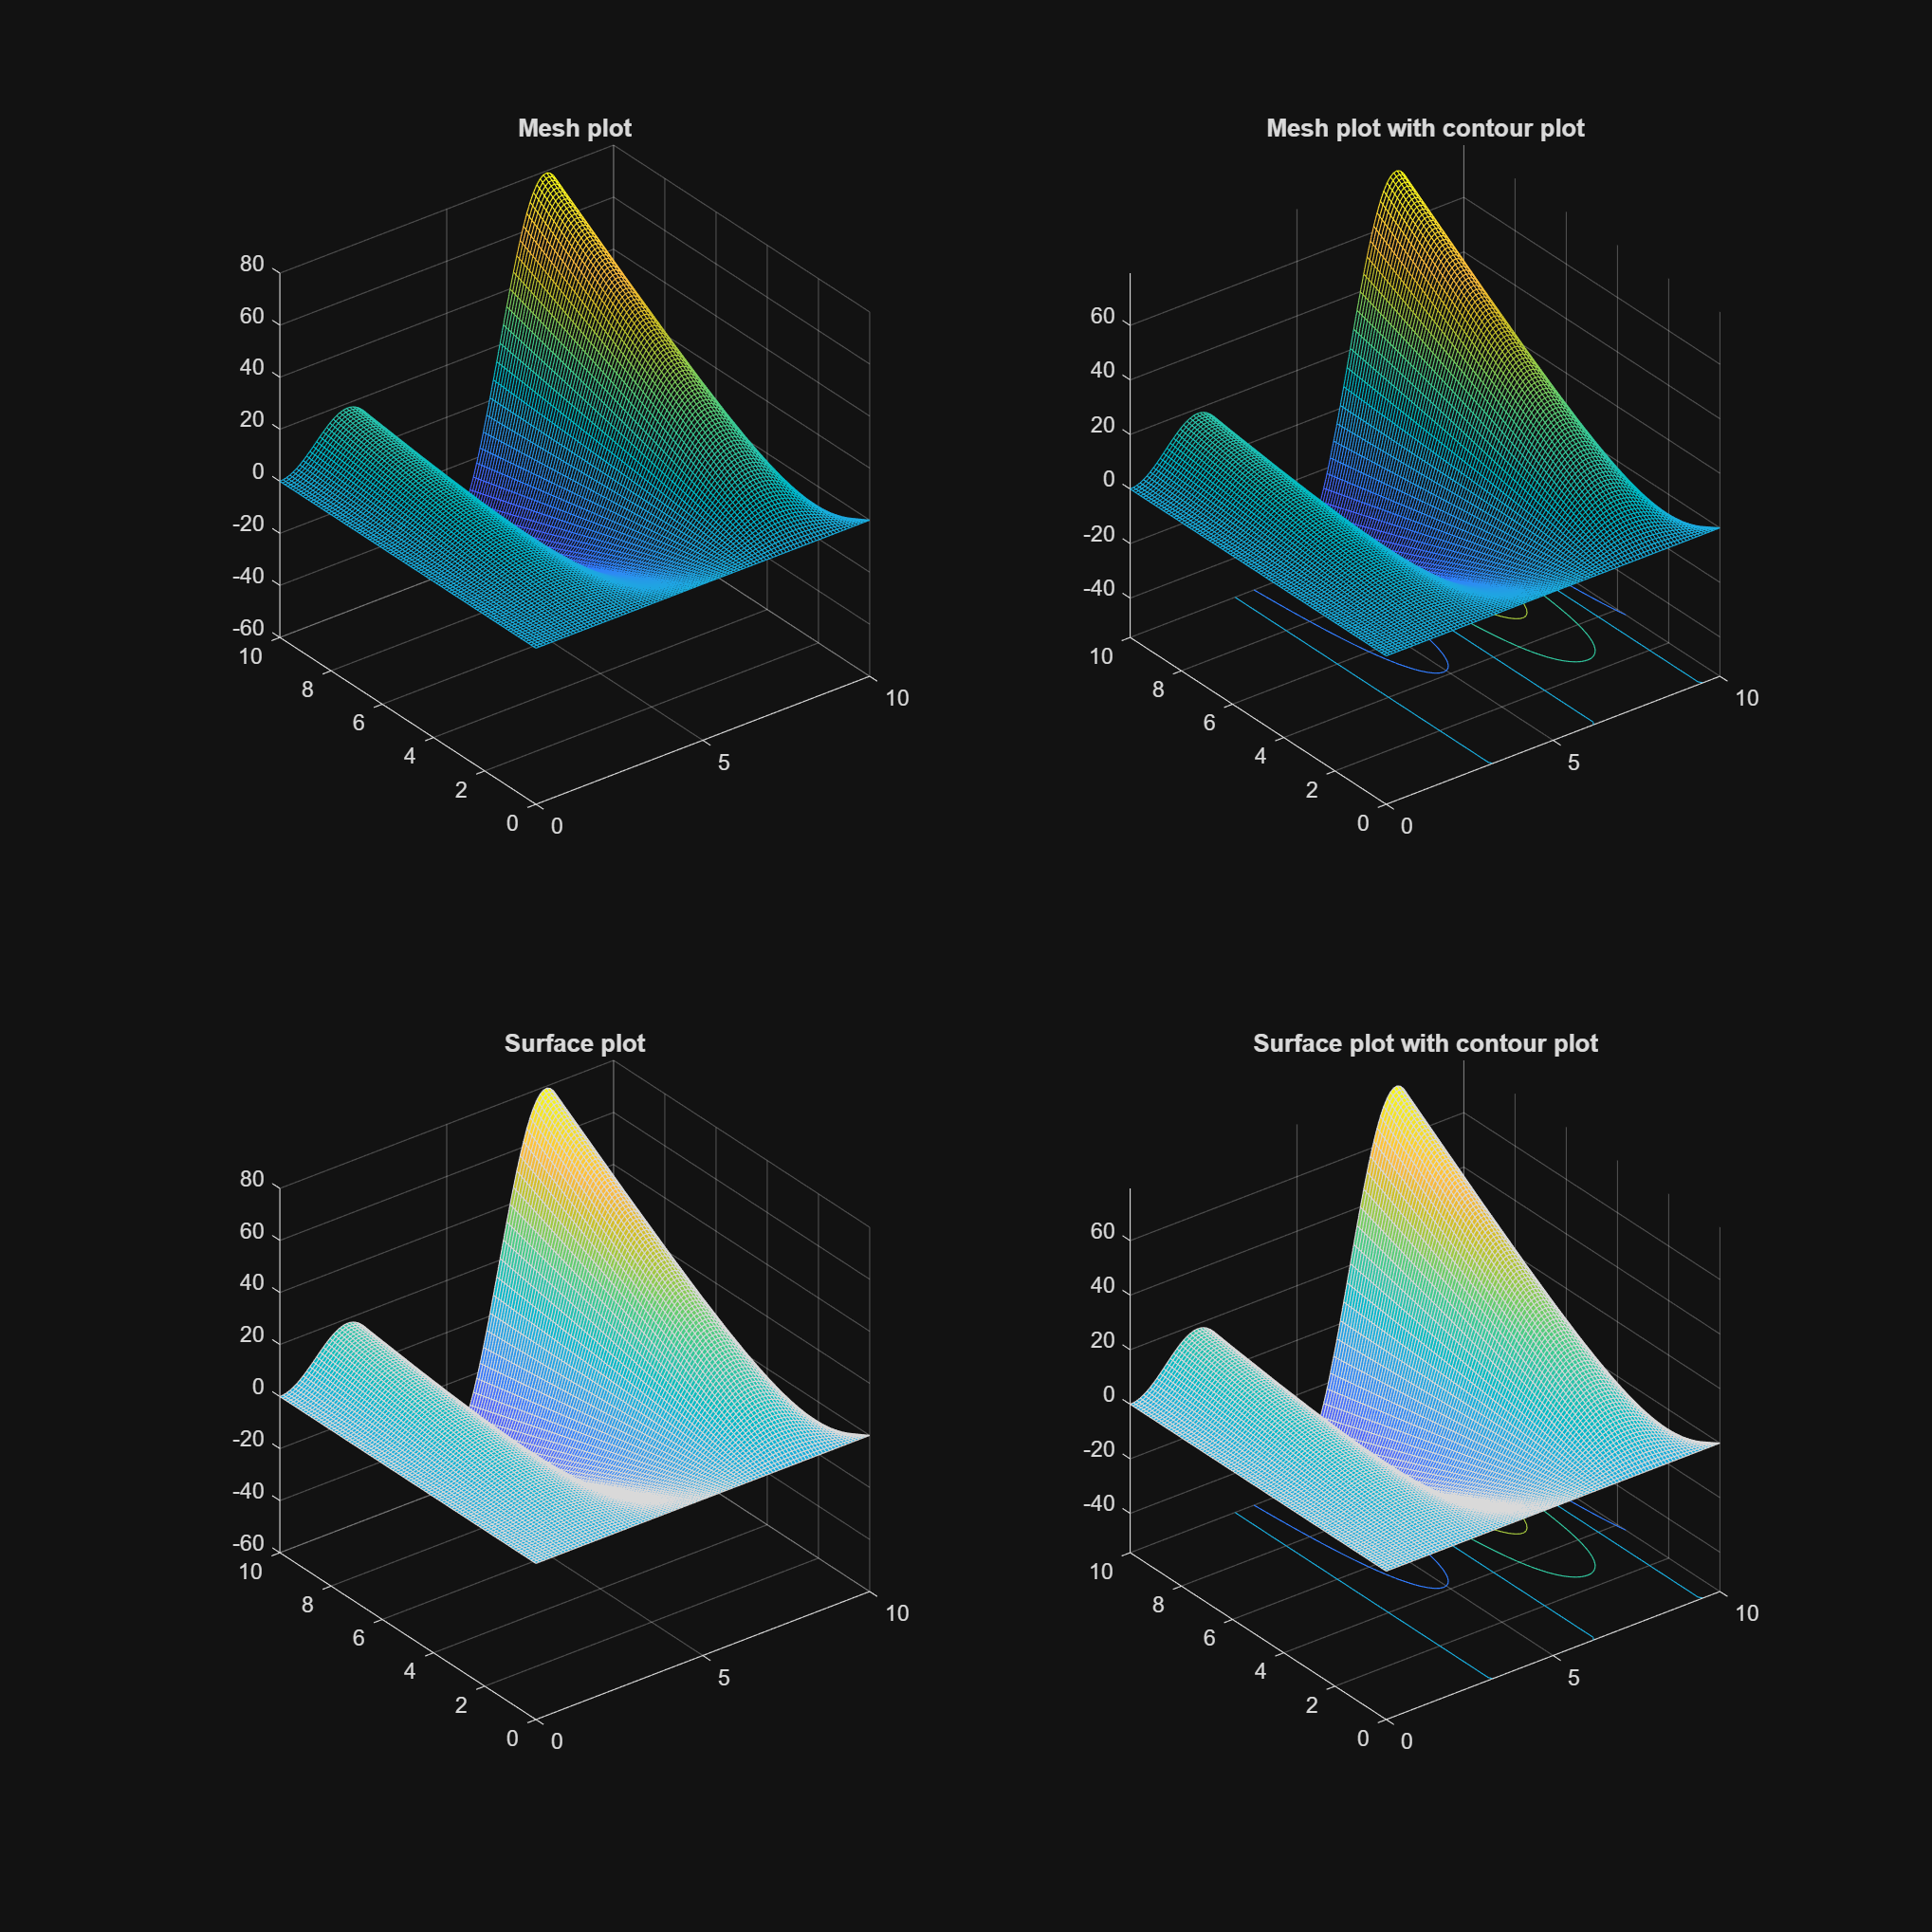

[X, Y] = meshgrid(0:0.1:10);

Z = sin(X) .* X .* Y;

figure('Position', [100, 100, 1200, 1200]);

subplot(2, 2, 1);
mesh(X, Y, Z);
title('Mesh plot');
pbaspect([1, 1, 1]);

subplot(2, 2, 2);
meshc(X, Y, Z);
title('Mesh plot with contour plot');
pbaspect([1, 1, 1]);

subplot(2, 2, 3);
surf(X, Y, Z);
title('Surface plot');
pbaspect([1, 1, 1]);

subplot(2, 2, 4);
surfc(X, Y, Z);
title('Surface plot with contour plot');
pbaspect([1, 1, 1]);

## Zadanie 3

**Podpunkt a)**

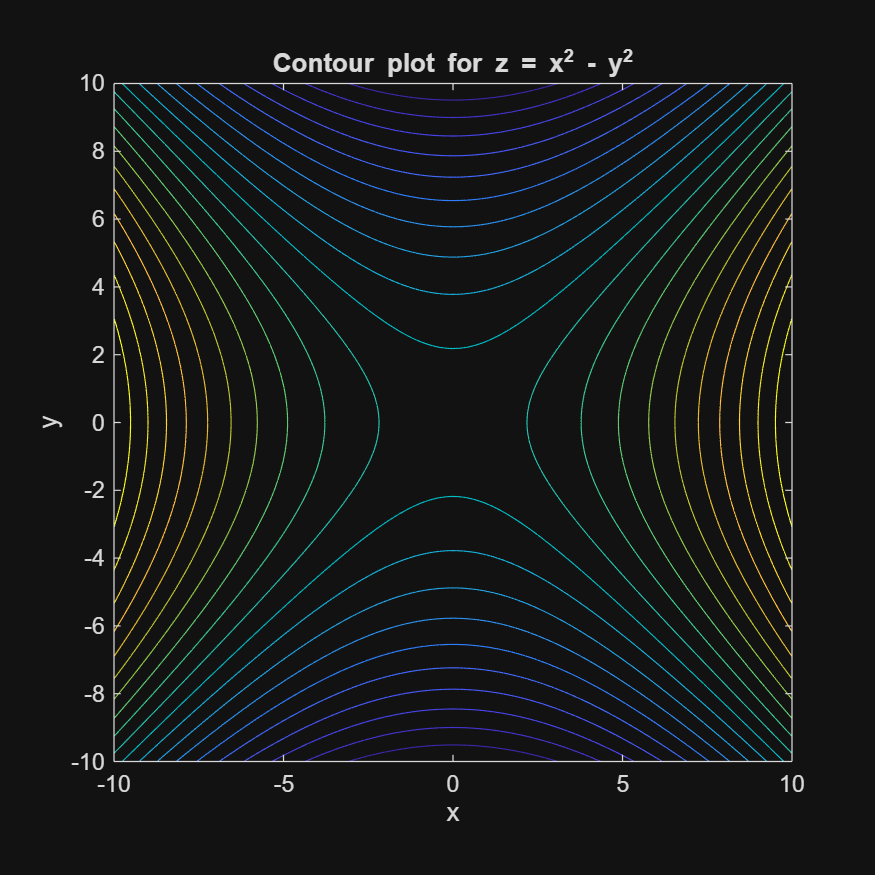

x = -10:0.1:10;
y = -10:0.1:10;

[X, Y] = meshgrid(x, y);

Z = X.^2 - Y.^2;

figure('Position', [100, 100, 500, 500]);
contour(X, Y, Z, 20);
title('Contour plot for z = x^2 - y^2');
xlabel('x');
ylabel('y');
axis equal;

**Podpunkt b)**

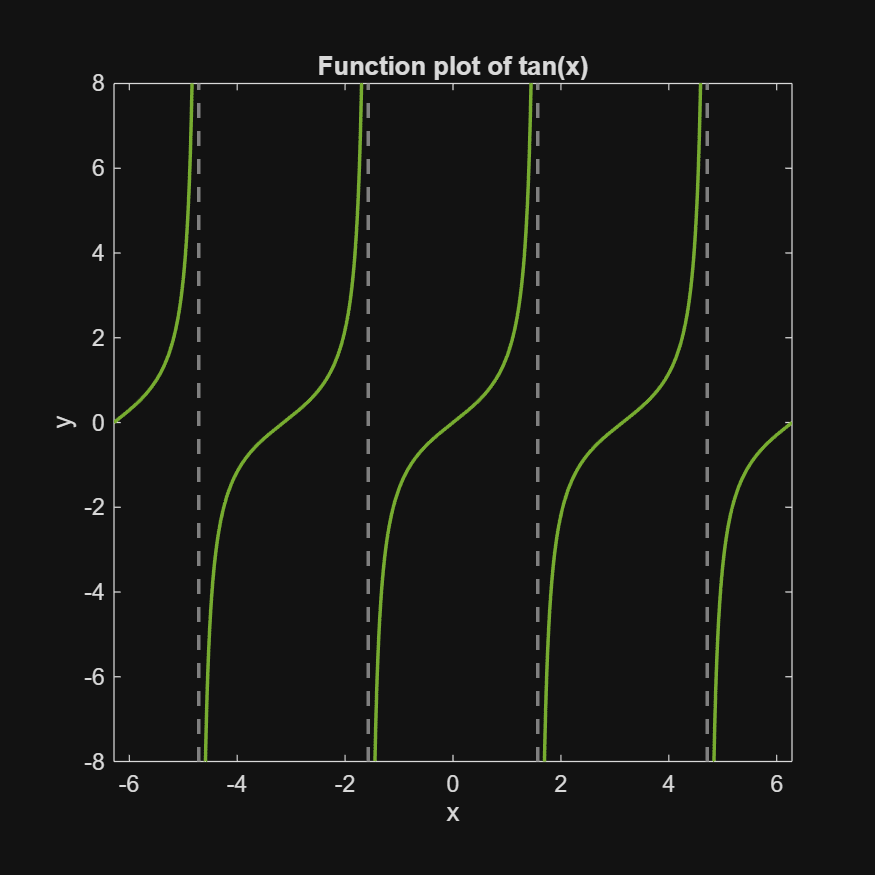

figure('Position', [100, 100, 500, 500]);
fplot(@(x) tan(x), [-2*pi, 2*pi], 'LineWidth', 1.5, 'Color', '#77AC30');
title('Function plot of tan(x)');
xlabel('x');
ylabel('y');
axis square;

**Podpunkt c)**

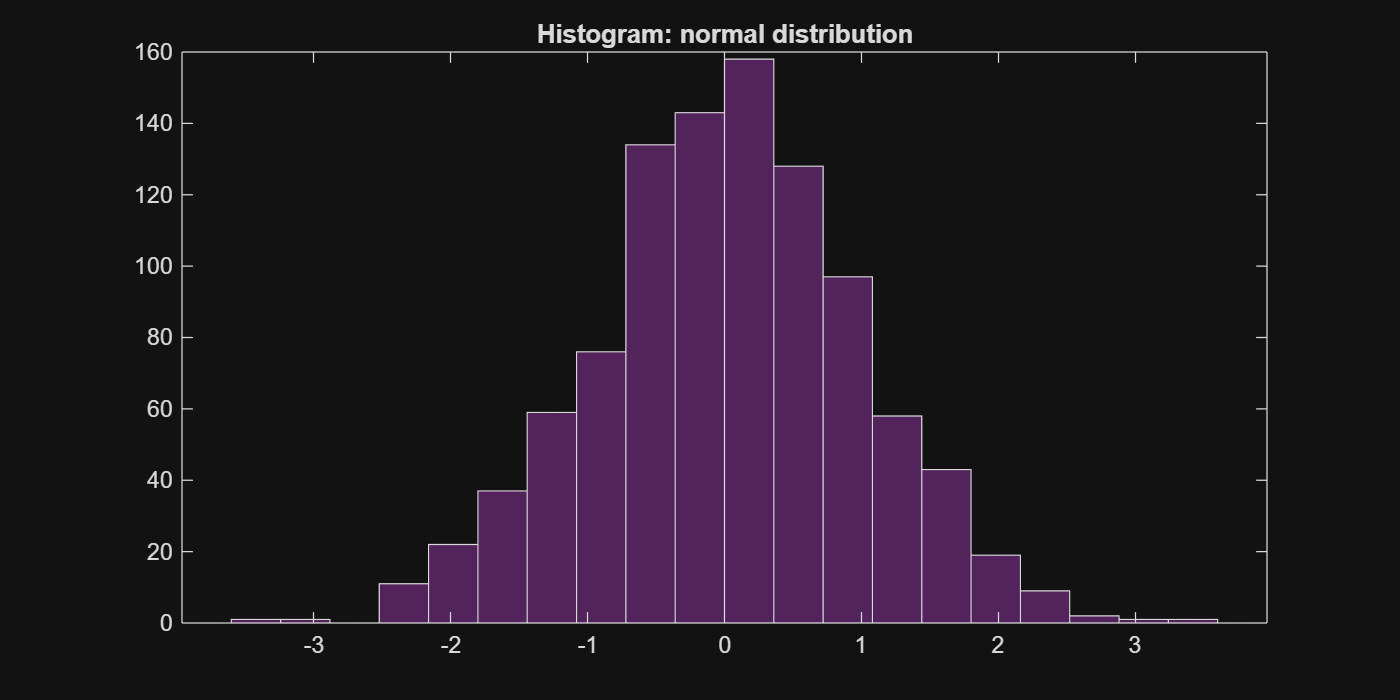

data = randn(1, 1000);

figure('Position', [100, 100, 800, 400]);
histogram(data, 20, 'FaceColor', '#7E2F8E');
title('Histogram: normal distribution');

**Podpunkt d)**

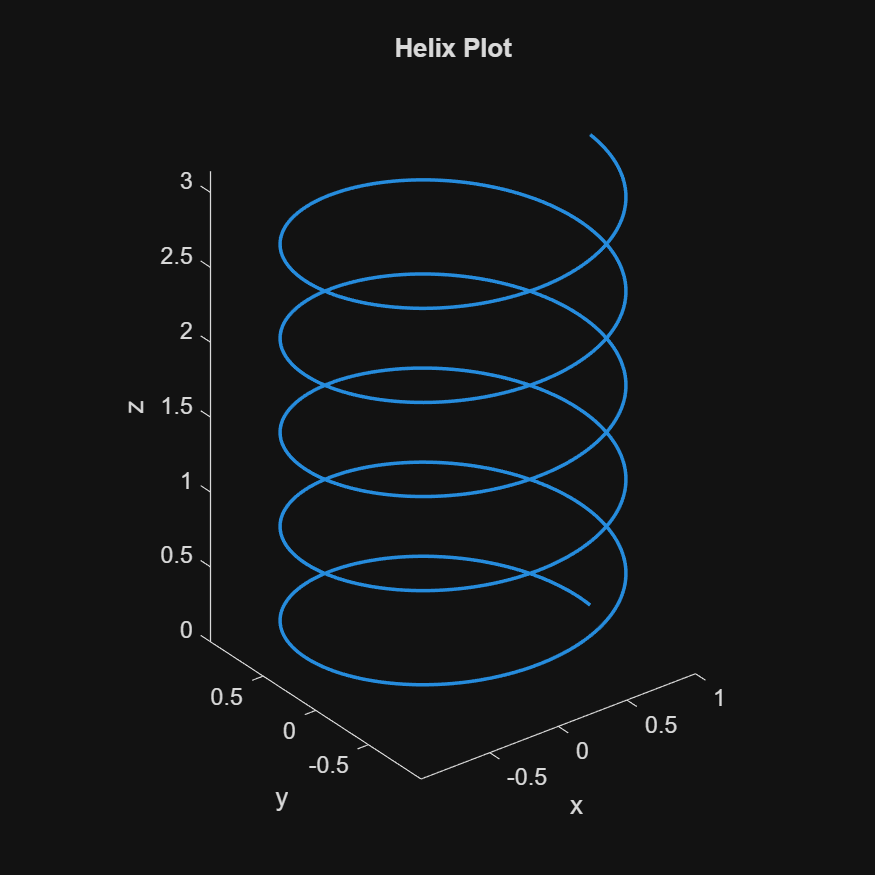

t = linspace(0, 10*pi, 1000);
r = 1;
c = 0.1;

x = r * cos(t);
y = r * sin(t);
z = c * t;

figure('Position', [100, 100, 500, 500]);
plot3(x, y, z, 'LineWidth', 1.5);
title('Helix Plot');
xlabel('x');
ylabel('y');
zlabel('z');
axis equal;

## Zadanie 4

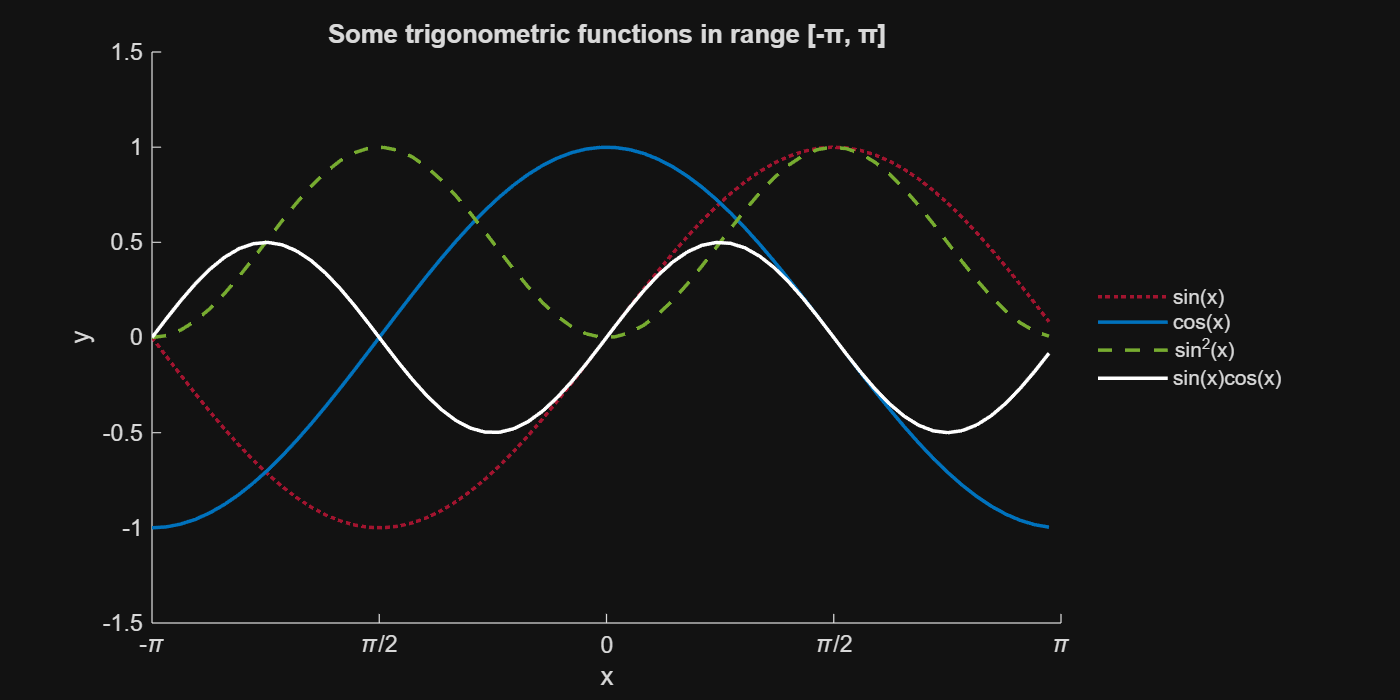

x = -pi:0.1:pi;

y1 = sin(x);
y2 = cos(x);
y3 = sin(x).^2;
y4 = sin(x).*cos(x);

figure('Position', [100, 100, 800, 400]);
hold on;

plot(x, y1, 'LineWidth', 1.5, 'Color', '#A2142F', 'LineStyle', ':');
plot(x, y2, 'LineWidth', 1.5, 'Color', '#0072BD', 'LineStyle', '-');
plot(x, y3, 'LineWidth', 1.5, 'Color', '#77AC30', 'LineStyle', '--');
plot(x, y4, 'LineWidth', 1.5, 'Color', '#FFFFFF');

title('Some trigonometric functions in range [-π, π]');
xlabel('x');
ylabel('y');
legend({'sin(x)', 'cos(x)', 'sin^2(x)', 'sin(x)cos(x)'}, 'Location','eastoutside');
legend('boxoff');
xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi', '\pi/2', '0', '\pi/2', '\pi'});
axis([-pi, pi, -1.5, 1.5]);

hold off;